# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report:

reportName = 'Report';
reportType = 'docx';
reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
               'IncludingPassingDiagnostics',true,'IncludingCommandWindowText',true); 
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Component\ParkingMeterGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING;
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\Component\\UnitTesting\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp


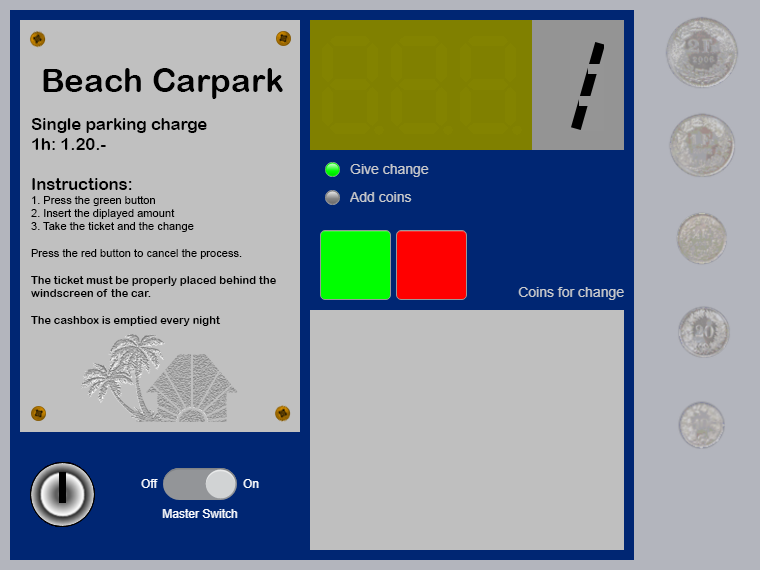

. Processing the test case #1...


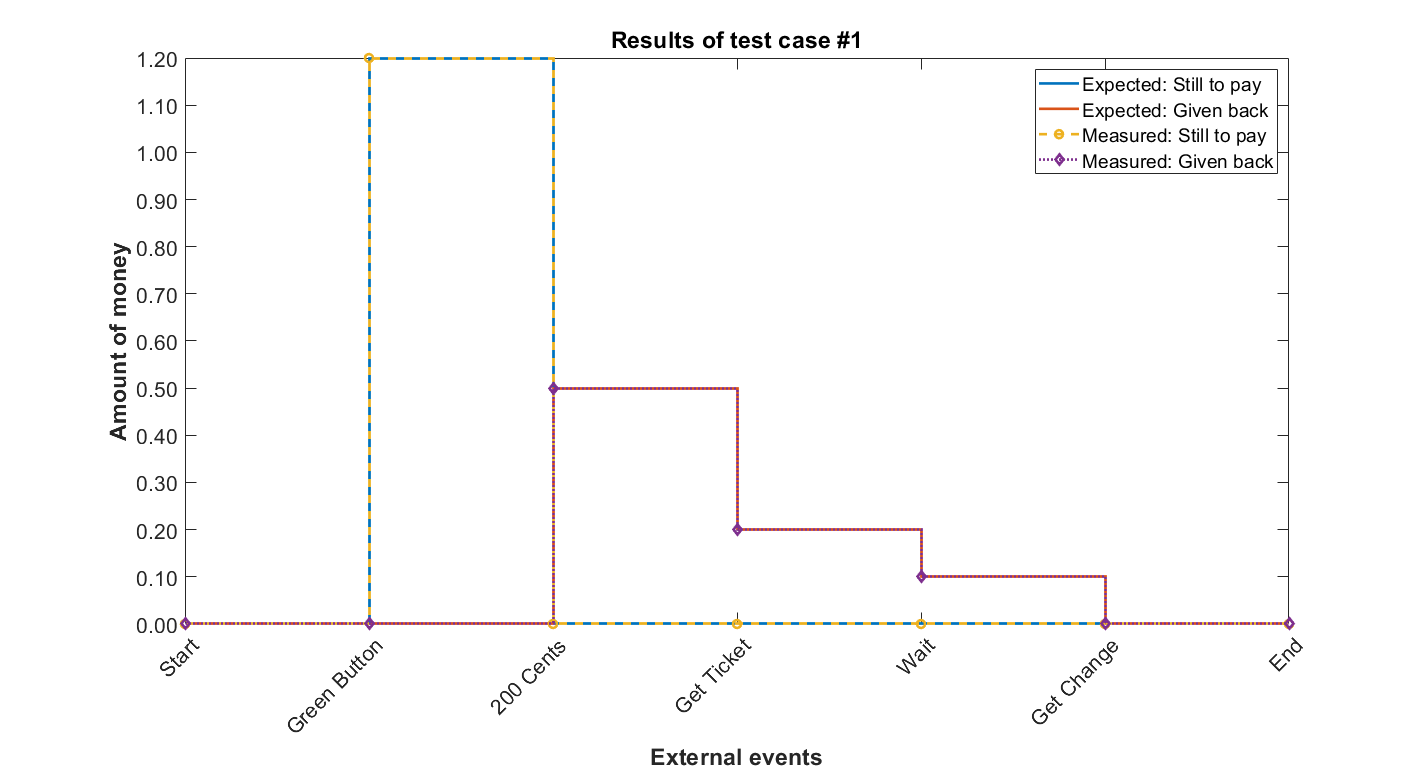


[Terse] Diagnostic logged (2021-02-04 20:04:28):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\88450eaf-a03b-47c2-9e74-ae4ad18e3719\Figure_50d681a5-6775-46bc-b443-c21f4a2effe7.fig
--> C:\Users\sebas\AppData\Local\Temp\88450eaf-a03b-47c2-9e74-ae4ad18e3719\Figure_50d681a5-6775-46bc-b443-c21f4a2effe7.png
.

 Processing the test case #2...


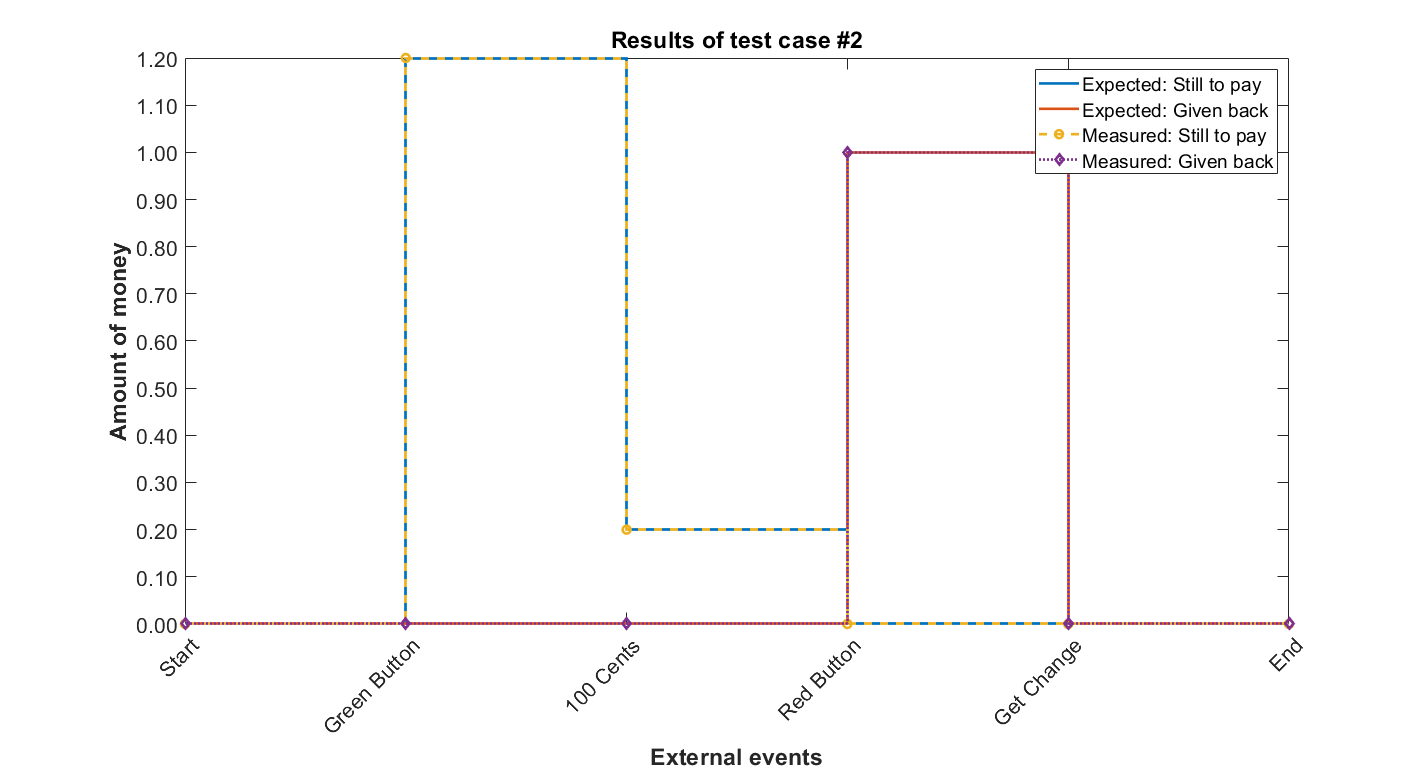


[Terse] Diagnostic logged (2021-02-04 20:04:53):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\88450eaf-a03b-47c2-9e74-ae4ad18e3719\Figure_6e651b5d-b542-4d65-87db-7c1b8885e34f.fig
--> C:\Users\sebas\AppData\Local\Temp\88450eaf-a03b-47c2-9e74-ae4ad18e3719\Figure_6e651b5d-b542-4d65-87db-7c1b8885e34f.png
.

 Processing the test case #3...


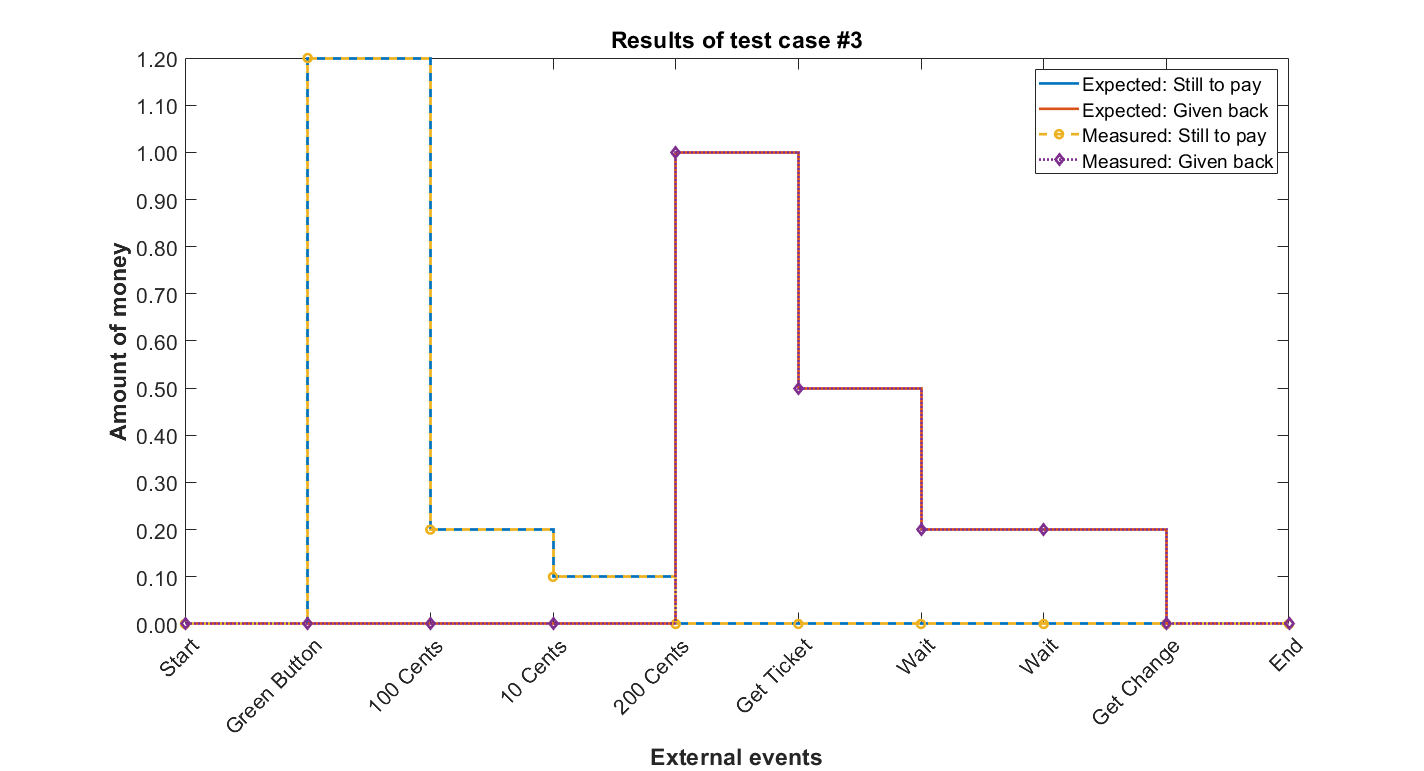


[Terse] Diagnostic logged (2021-02-04 20:05:23):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\88450eaf-a03b-47c2-9e74-ae4ad18e3719\Figure_b7386fc0-7ec9-4d61-a37e-704adf9059fd.fig
--> C:\Users\sebas\AppData\Local\Temp\88450eaf-a03b-47c2-9e74-ae4ad18e3719\Figure_b7386fc0-7ec9-4d61-a37e-704adf9059fd.png
.
Done TestApp
__________

Generating test report. Please wait.
    Preparing content for the test report.


    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 D:\GitHub\C_Code_Integration\MATLAB\Work\Report.docx
Code coverage report has been saved to:
 C:\Users\sebas\AppData\Local\Temp\tp016c8007_0f31_4b01_9876_67f4f7a79268\index.html


% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                            Name                            Passed    Failed    Incomplete    Duration      Details   
    ____________________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_1_StraightTicketPurchase'       }    true      false       false        26.812     {1×1 struct}
    {'TestApp/testCase_2_CancelTicketPurchase'         }    true      false       false        23.783     {1×1 struct}
    {'TestApp/testCase_3_BiggestChangeOnTicketPurchase'}    true      false       false         30.35     {1×1 struct}

